**Cargar y Preprocesar Datos**

Como primer paso se opto por cargar los datos de la vairable PhysionetData.mat y visualizar. 

load PhysionetData.mat
cinco_signals = Signals(1:5,1)

cinco_signals = 5×1 cell array
    {1×9000  double}
    {1×9000  double}
    {1×18000 double}
    {1×9000  double}
    {1×18000 double}


cinco_labels = Labels(1:5,1)

cinco_labels = 5×1 categorical array
     N 
     N 
     N 
     A 
     A 


Con este comando se busca encontrar dentro de la variable LABELS las cantidades de señales con ritmo Sinusal Normal (N) y con Arritmia (A).

figure(1)
summary(Labels)

     A       738 
     N      5050 


Del mismo modo con este comando se buscó hacer un histograma con el fin de mostrar las longitudes de las diferentes señales.

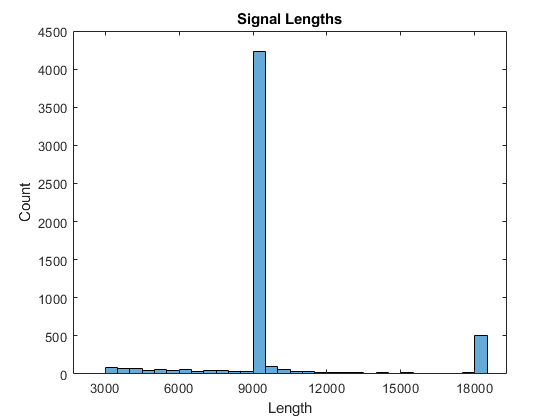

figure(2)
plotSignalLengths(Signals)

Asimismo se usó este comando para observar un segmento de una señal de las dos clases de señales.

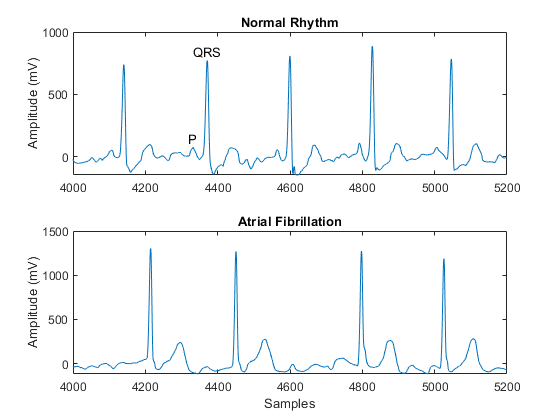

figure(3)
visualizeECGSignals(Signals)

No obstante se necesitaba que las señales de** EGG** tuvieran una longitud de 9000 muestras y para este fin se opto por utiliar el comando** segmentSignals**, con esto en mente se busco guardar dichas longitudes en una variable llamada nuesegmentSignals.

figure(4)
nuesegmentSignals = segmentSignals(Signals,Labels)

nuesegmentSignals = 5655×1 cell array
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
  

Con este comando se búsco obtener un nuevo histograma pero con la nueva redimension.

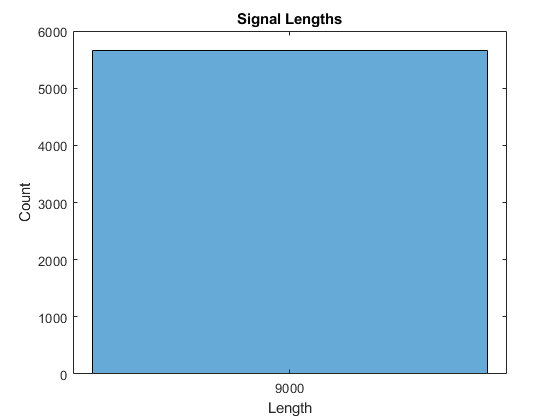

figure(5)
plotSignalLengths(nuesegmentSignals)

Después de lo mencionado anteriormente se cargaron los datos `ECG_ML_Features_DK.mat.`

load ECG_ML_Features_DK.mat

Se creo una variable con el fin de que almacenara todos los nombres de las características.

variableNames = ECGFeatures_DK.Properties.VariableNames;

Con esta serie de comandos se busco dividir los datos en 2 variables las cuales son `TrainData `y `TestData`, del mismo modo se dividieron un 80% de los datos.

n = length(ECGFeatures_DK.Variables);
partition = cvpartition(n,"Holdout",0.2);

 